# Trabajo práctico: Filtrado digital FIR

## 3) Filtro Moving Average con oversampling

El objetivo de este ejercicio es el de cuantificar los efectos de elevar la frecuencia de muestreo en un caso de un filtro MA.

### a) Tome el ejercicio 1 ya resuelto.

load("ej1_data.mat");

### b) Eleve la frecuencia de muestreo, fs, y el orden N, de tal manera de no alterar la frecuencia de corte, fco, del filtro MA. Tome los valores de fs iguales a 2.000, 5.000 y 10.000.

fS_vect = [2e3 5e3 10e3];
N_max_vect = zeros(1, length(fS_vect));

for i=1:length(N_max_vect)
    N_max_vect(i) = round(sqrt(0.885894^2*fS_vect(i)^2/fco^2 - 1));
end

kernel1 = ones(1, N_max_vect(1)) / N_max_vect(1);
kernel2 = ones(1, N_max_vect(2)) / N_max_vect(2);
kernel3 = ones(1, N_max_vect(3)) / N_max_vect(3);

### c) Cuantifique la diferencia entre la señal de entrada y la señal de salida utilizando la función rmse() (root squarred error).

signal_f1 = filter(kernel1, 1, signal_n);
signal_f2 = filter(kernel2, 1, signal_n);
signal_f3 = filter(kernel3, 1, signal_n);

err = ones(1, length(fS_vect));
err(1) = rmse(signal_f1, signal);
err(2) = rmse(signal_f2, signal);
err(3) = rmse(signal_f3, signal);

disp("Freq. sampling = " + fS_vect(1) + " -- err = " + err(1));

Freq. sampling = 2000 -- err = 0.37247


disp("Freq. sampling = " + fS_vect(2) + " -- err = " + err(2));

Freq. sampling = 5000 -- err = 0.77167


disp("Freq. sampling = " + fS_vect(3) + " -- err = " + err(3));

Freq. sampling = 10000 -- err = 0.78509


### d) Determine qué efecto tiene en el error entre ambas señales aumentar la frecuencia de muestreo.

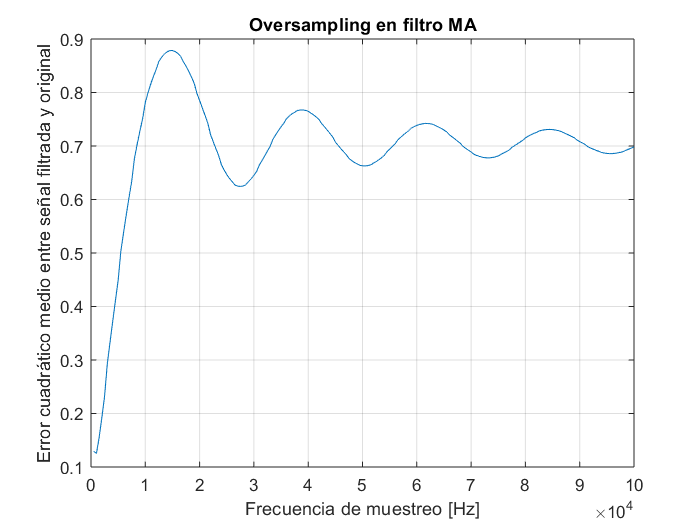

fS_vect = 500:500:100e3;
N_max_vect = zeros(1, length(fS_vect));
err = zeros(1, length(fS_vect));
for i=1:length(fS_vect)
    N_max_vect(i) = round(sqrt(0.885894^2*fS_vect(i)^2/fco^2 - 1));
    N = round(N_max_vect(i) / 2);
    kernel = ones(1, N) / N;
    signal_f = filter(kernel, 1, signal_n);
    err(i) = rmse(signal_f, signal);
end

figure(1)
plot(fS_vect, err);
grid on;
title("Oversampling en filtro MA");
xlabel("Frecuencia de muestreo [Hz]");
ylabel("Error cuadrático medio entre señal filtrada y original");